# Ex08. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Plot Transfer Functions and Response Signals

 This assignment involves creating the 3d figure of the transfer function H(z) and response signal h[n] and s[n]. For the numerical computation, the discrete time index n ranges from 0 to 10 with an increment of 0.1. The frequency domain ω is sampled at intervals of 0.1 (from -pi to pi). The resulting waveforms are organized into a 2 * 2 subplot grid for comparative analysis.

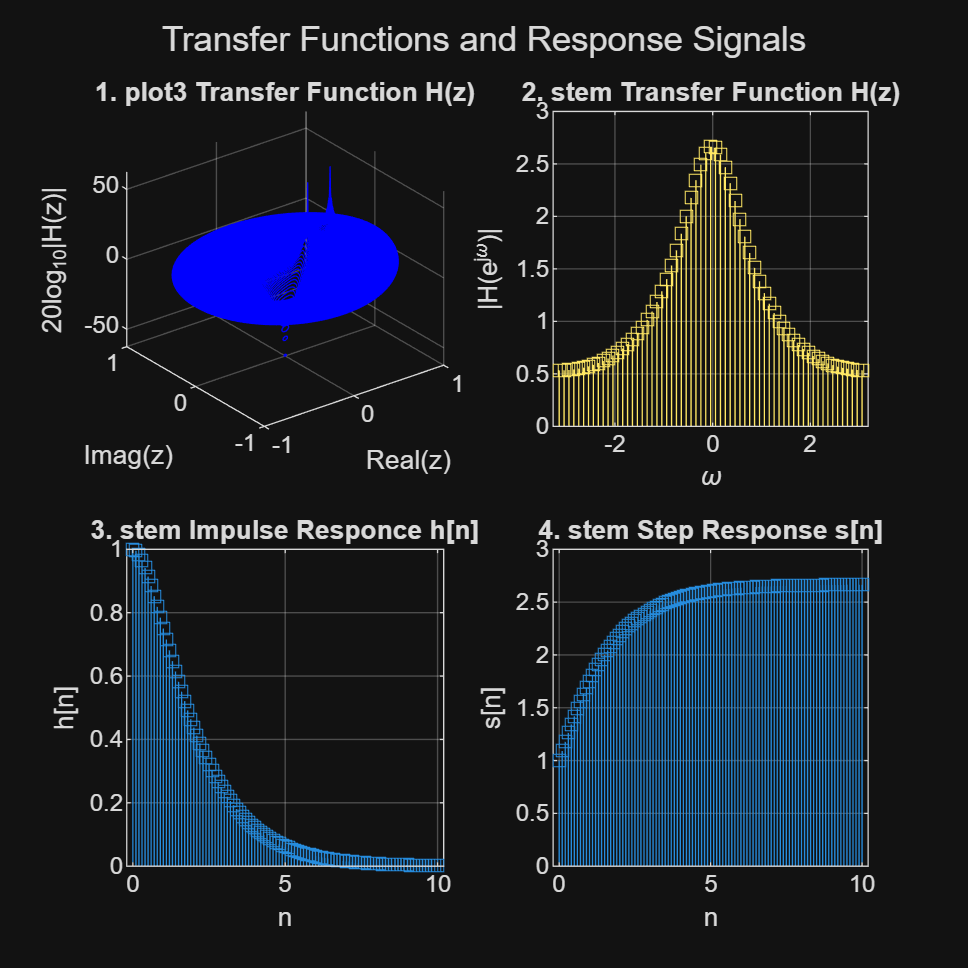

r = 0:0.01:1;
omega1 = -pi:0.01:pi;
omega2 = -pi:0.1:pi;
n = 0:0.1:10;

H = @(z) (z.^2) ./ (z.^2 - (3/4)*z + (1/8));
h = @(n) (2 * (1/2).^n - (1/4).^n) .* (n >= 0);
s = @(n) ((8/3) + (1/3)*((1/4).^n) -2 * ((1/2).^n)) .* (n >= 0);

figure('Position', [100, 100, 800, 800]);

subplot(2, 2, 1);
[R, W] = meshgrid(r, omega1);
Z = R .* exp(1j * W);
p1 = plot3(real(Z), imag(Z), 20*log10(abs(H(Z))), 'b');
title('1. plot3 Transfer Function H(z)');
xlabel('Real(z)');
ylabel('Imag(z)');
zlabel('20log_{10}|H(z)|');
grid on;

subplot(2, 2, 2);
[R, W] = meshgrid(r, omega2);
Z = 1 .* exp(1j * W);
p2 = stem(omega2, abs(H(Z)), 's-');
title('2. stem Transfer Function H(z)');
xlabel('\omega');
ylabel('|H(e^{j\omega})|');
grid on;

subplot(2, 2, 3);
p3 = stem(n, h(n), 's-');
title('3. stem Impulse Responce h[n]');
xlabel('n');
ylabel('h[n]');
grid on;

subplot(2, 2, 4);
p4 = stem(n, s(n), 's-');
title('4. stem Step Response s[n]');
xlabel('n');
ylabel('s[n]');
grid on;

sgtitle("Transfer Functions and Response Signals");

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem.